## RANDOM FOREST

- Random forest is performed on the original data without specifying the categorical variables. And then 5fold and 10-fold cross validation is done.

- Data is then modified. Modification - Positively correlated features are used to perform random forest, followed by 5-fold and 10-fold cross validation 

load C:\Users\aksha\HCVEgyptData.mat
disp(HCV)

    Age    Gender    BMI    Fever    NauseaVomting    Headache    Diarrhea    Fatiguegeneralizedboneache    Jaundice    Epigastricpain     WBC        RBC        HGB       Plat       AST1    ALT1    ALT4    ALT12    ALT24    ALT36    ALT48    ALTafter24w     RNABase         RNA4         RNA12         RNAEOT        RNAEF       BaselinehistologicalGrading    Baselinehistologicalstaging
    ___    ______    ___    _____    ________

class(HCV)

ans = 'table'

size(HCV)

ans =         1385          29



% Find missing data
sum(sum(ismissing(HCV)))

ans = 0

dat=table2array(HCV);

# 1. Random Forest on Original Data

x=dat(:,1:27);
y=categorical(dat(:,29));
[Xtrain1, Ytrain1, Xtest1, Ytest1]=trainTestSplit(x,y,0.7);
RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on")

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:             [969x27]
                    Training Y:              [969x1]
                        Method:       classification
                 NumPredictors:                   27
         NumPredictorsToSample:                    6
                   MinLeafSize:                   10
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


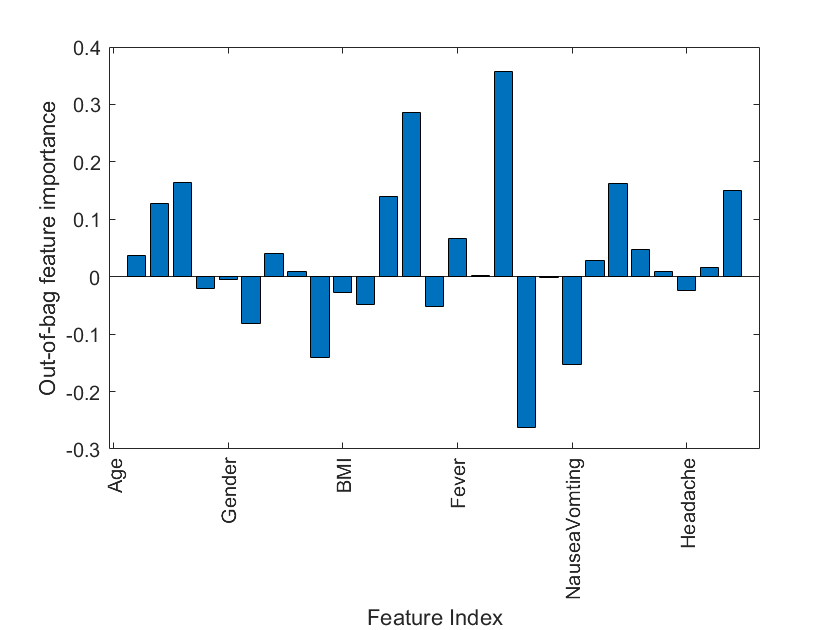

bar(RFmodel.OOBPermutedPredictorDeltaError)
xlabel('Feature Index')
ylabel('Out-of-bag feature importance')
xticklabels(HCV.Properties.VariableNames(1:28))
xtickangle(90)

Ypred=predict(RFmodel,Xtest1); % RF gives output in cell array format
Ypred=categorical(Ypred); % cell array to categorical array
sum(Ypred==Ytest1)/length(Ytest1) % accuracy

ans = 0.2380

confusionmat(double(Ytest1),double(Ypred))

Class List in given sample
     1
     2
     3
     4


Total Instance = 416
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           7                22                41                44      
    Actual_class2          11                16                39                45      
    Actual_class3          12                10                35                36      
    Actual_class4          14                12                31                41      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      7    22    41    44
    11    16    39    45
    12    10    35    36
    14    12    31    41


## Achieved 25.48% accuracy using original data.

5-Fold Cross-Validation 

x1=dat(:,1:27);
y1=categorical(dat(:,29));
fold=5;
index1=crossvalind('kfold',size(Xtrain1,1),fold);
accuracy5_=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain1=x1(train,:);
    Xtest1=x1(test,:);
    Ytrain1=y1(train,:);
    Ytest1=y1(test,:);
    
    %Random Forest
    RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on");
    Ypred=predict(RFmodel,Xtest1); % RF gives output in cell array format
    Ypred=categorical(Ypred); % cell array to categorical array
   
    % For model accuracy
    accuracy5_(i)=sum(Ypred==Ytest1)/length(Ytest1)
    confusionmat(double(Ytest1),double(Ypred))
end

accuracy5_ =     0.2375         0         0         0         0


Class List in given sample
     1
     2
     3
     4


Total Instance = 80
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          1                 2                  8                2       
    Actual_class2          1                 3                  5                6       
    Actual_class3          5                 7                  8                8       
    Actual_class4          5                 2                 10                7       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      1     2     8     2
     1     3     5     6
     5     7     8     8
     5     2    10     7


accuracy5_ =     0.2375    0.2500         0         0         0


Class List in given sample
     1
     2
     3
     4


Total Instance = 80
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          1                 2                 12                5       
    Actual_class2          1                 3                 13                2       
    Actual_class3          1                 2                  9                9       
    Actual_class4          3                 2                  8                7       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      1     2    12     5
     1     3    13     2
     1     2     9     9
     3     2     8     7


accuracy5_ =     0.2375    0.2500    0.2963         0         0


Class List in given sample
     1
     2
     3
     4


Total Instance = 81
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          3                 0                  9                3       
    Actual_class2          2                 4                  7                8       
    Actual_class3          3                 5                 13                2       
    Actual_class4          4                 6                  8                4       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      3     0     9     3
     2     4     7     8
     3     5    13     2
     4     6     8     4


accuracy5_ =     0.2375    0.2500    0.2963    0.2469         0


Class List in given sample
     1
     2
     3
     4


Total Instance = 81
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          2                 4                  5                10      
    Actual_class2          1                 5                  6                 6      
    Actual_class3          2                 5                  9                 6      
    Actual_class4          0                 5                 11                 4      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      2     4     5    10
     1     5     6     6
     2     5     9     6
     0     5    11     4


accuracy5_ =     0.2375    0.2500    0.2963    0.2469    0.2500


Class List in given sample
     1
     2
     3
     4


Total Instance = 80
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          0                 3                 10                 6      
    Actual_class2          1                 5                 10                 2      
    Actual_class3          1                 3                  7                11      
    Actual_class4          1                 1                 11                 8      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      0     3    10     6
     1     5    10     2
     1     3     7    11
     1     1    11     8


accuracy5_

accuracy5_ =     0.2375    0.2500    0.2963    0.2469    0.2500


avg_accuracy_5=mean(accuracy5_)

avg_accuracy_5 = 0.2561

## Achieved 25.61% accuracy for 5-fold using original data.

10-Fold Cross-Validation 

x1=dat(:,1:27);
y1=categorical(dat(:,29));
fold=10;
index1=crossvalind('kfold',size(Xtrain1,1),fold);
accuracy10_=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain1=x1(train,:);
    Xtest1=x1(test,:);
    Ytrain1=y1(train,:);
    Ytest1=y1(test,:);
    
    %Random Forest
    RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on");
    Ypred=predict(RFmodel,Xtest1); % RF gives output in cell array format
    Ypred=categorical(Ypred); % cell array to categorical array
   
    % For model accuracy
    accuracy10_(i)=sum(Ypred==Ytest1)/length(Ytest1);
    confusionmat(double(Ytest1),double(Ypred))
end

Class List in given sample
     1
     2
     3
     4


Total Instance = 32
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          2                 2                 1                 1       
    Actual_class2          1                 2                 2                 0       
    Actual_class3          2                 1                 2                 5       
    Actual_class4          0                 4                 5                 2       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      2     2     1     1
     1     2     2     0
     2     1     2     5
     0     4     5     2


Class List in given sample
     1
     2
     3
     4


Total Instance = 32
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          1                 1                 1                 2       
    Actual_class2          2                 1                 4                 2       
    Actual_class3          1                 2                 3                 4       
    Actual_class4          1                 2                 1                 4       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      1     1     1     2
     2     1     4     2
     1     2     3     4
     1     2     1     4


Class List in given sample
     1
     2
     3
     4


Total Instance = 33
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          1                 1                 5                 4       
    Actual_class2          1                 3                 1                 4       
    Actual_class3          0                 0                 5                 2       
    Actual_class4          2                 0                 3                 1       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      1     1     5     4
     1     3     1     4
     0     0     5     2
     2     0     3     1


Class List in given sample
     1
     2
     3
     4


Total Instance = 32
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          1                 0                 4                 2       
    Actual_class2          1                 0                 6                 1       
    Actual_class3          2                 0                 5                 2       
    Actual_class4          2                 1                 5                 0       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      1     0     4     2
     1     0     6     1
     2     0     5     2
     2     1     5     0


Class List in given sample
     1
     2
     3
     4


Total Instance = 33
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          1                 0                 2                 1       
    Actual_class2          3                 0                 7                 1       
    Actual_class3          1                 0                 3                 3       
    Actual_class4          2                 2                 4                 3       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      1     0     2     1
     3     0     7     1
     1     0     3     3
     2     2     4     3


Class List in given sample
     1
     2
     3
     4


Total Instance = 32
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          0                 0                 2                 2       
    Actual_class2          3                 0                 2                 4       
    Actual_class3          4                 0                 4                 5       
    Actual_class4          2                 1                 1                 2       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      0     0     2     2
     3     0     2     4
     4     0     4     5
     2     1     1     2


Class List in given sample
     1
     2
     3
     4


Total Instance = 32
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          0                 1                 5                 5       
    Actual_class2          0                 1                 3                 0       
    Actual_class3          0                 4                 3                 1       
    Actual_class4          1                 0                 4                 4       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      0     1     5     5
     0     1     3     0
     0     4     3     1
     1     0     4     4


Class List in given sample
     1
     2
     3
     4


Total Instance = 32
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          4                 0                 0                 5       
    Actual_class2          1                 3                 2                 2       
    Actual_class3          1                 0                 5                 1       
    Actual_class4          1                 0                 6                 1       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      4     0     0     5
     1     3     2     2
     1     0     5     1
     1     0     6     1


Class List in given sample
     1
     2
     3
     4


Total Instance = 32
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          1                 2                 4                 3       
    Actual_class2          0                 1                 3                 0       
    Actual_class3          0                 1                 4                 4       
    Actual_class4          0                 2                 4                 3       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      1     2     4     3
     0     1     3     0
     0     1     4     4
     0     2     4     3


Class List in given sample
     1
     2
     3
     4


Total Instance = 32
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          0                 0                 6                 2       
    Actual_class2          2                 1                 3                 0       
    Actual_class3          0                 1                 5                 4       
    Actual_class4          1                 0                 3                 4       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      0     0     6     2
     2     1     3     0
     0     1     5     4
     1     0     3     4


accuracy10_

accuracy10_ =     0.2500    0.2813    0.3030    0.1875    0.2121    0.1875    0.2500    0.4063    0.2813    0.3125


avg_accuracy_10=mean(accuracy10_)

avg_accuracy_10 = 0.2671

## Achieved 26.71% accuracy for 10-fold using original data.

[https://medium.com/predicting-the-stage-of-hepatitis-c-in-patients/in-this-blog-i-am-going-to-predict-the-stage-of-hepatitis-c-in-patients-suffering-from-hepatitis-8779d3482ad5](https://medium.com/predicting-the-stage-of-hepatitis-c-in-patients/in-this-blog-i-am-going-to-predict-the-stage-of-hepatitis-c-in-patients-suffering-from-hepatitis-8779d3482ad5)

# 2. Execution

% Find Pearson's correlation coefficient of each feature with grade
outrel=zeros(28,2);
for i=1:27
    feax=dat(:,i);
    gr=dat(:,28);
    st=dat(:,29);
    outrel(i,1)=corr(feax,gr);
    outrel(i,2)=corr(feax,gr);
end
t=array2table(outrel,'RowNames',HCV.Properties.VariableNames(1:28),'VariableNames',{'Grade corr','Stage corr'})

t = 28×2 table
                                  Grade corr    Stage corr
                                  __________    __________

    Age                            -0.040705     -0.040705
    Gender                          0.014559      0.014559
    BMI                            -0.023045     -0.023045
    Fever                          -0.031563     -0.031563
    NauseaVomting                  -0.056782     -0.056782
    Headache                       -0.011241     -0.011241
    Diarrhea                        0.031891      0.031891
    Fatiguegeneralizedboneache     -0.022027     -0.022027
    Jaundice                      -0.0077696    -0.0077696
    Epigastricpain                -0.0056327    -0.0056327
    WBC                       

%take only positively correlated features
data=zeros(1385,sum(outrel(:,1)>0));
id=zeros(1,sum(outrel(:,1)>0));
k=1;
for i=1:27
    if outrel(i,1)>0
        id(k)=i;
        data(:,k)=dat(:,i);
        k=k+1;
    end
end
data

data =            1           1        7425          14      112132           5           5           5           5
           1           1       12101          10      129367          57         123          44       31085
           1           2        4178          12      151522           5           5           5      558829
           2           2        6490          10      146457          48          77          33      582301
           1           1        3661          11      187684          94          90          30      242861
           2           1       11785          15      131228          73         114          29           5
           2           2       11620          12      177261          84          80          28      635157
           2           2        7335          11      216176          96          53          39      506296
           1           2       10480          12      148889         122          39          45      203042
           1

id

id =      2     7    11    13    14    20    21    22    27


new_data=array2table(data,'VariableNames',HCV.Properties.VariableNames([id]))

new_data = 1385×9 table
    Gender    Diarrhea     WBC     HGB       Plat       ALT36    ALT48    ALTafter24w      RNAEF   
    ______    ________    _____    ___    __________    _____    _____    ___________    __________

      1          1         7425    14     1.1213e+05       5        5          5                  5
      1          1        12101    10     1.2937e+05      57      123         44              31085
      1          2         4178    12     1.5152e+05       5        5          5         5.5883e+05
      2          2         6490    10     1.4646e+05      48       77         33          5.823e+05
      1          1         3661    11     1.8768e+05      94       90

# Random Forest on Positively correlated features of the dataset

x=new_data;
y=categorical(dat(:,29));
[Xtrain1, Ytrain1, Xtest1, Ytest1]=trainTestSplit(x,y,0.7);
RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on")

RFmodel =   TreeBagger
Ensemble with 100 bagged decision trees:
                    Training X:              [969x9]
                    Training Y:              [969x1]
                        Method:       classification
                 NumPredictors:                    9
         NumPredictorsToSample:                    3
                   MinLeafSize:                   10
                 InBagFraction:                    1
         SampleWithReplacement:                    1
          ComputeOOBPrediction:                    1
 ComputeOOBPredictorImportance:                    1
                     Proximity:                   []
                    ClassNames:             '1'             '2'             '3'             '4'

  Properties, Methods


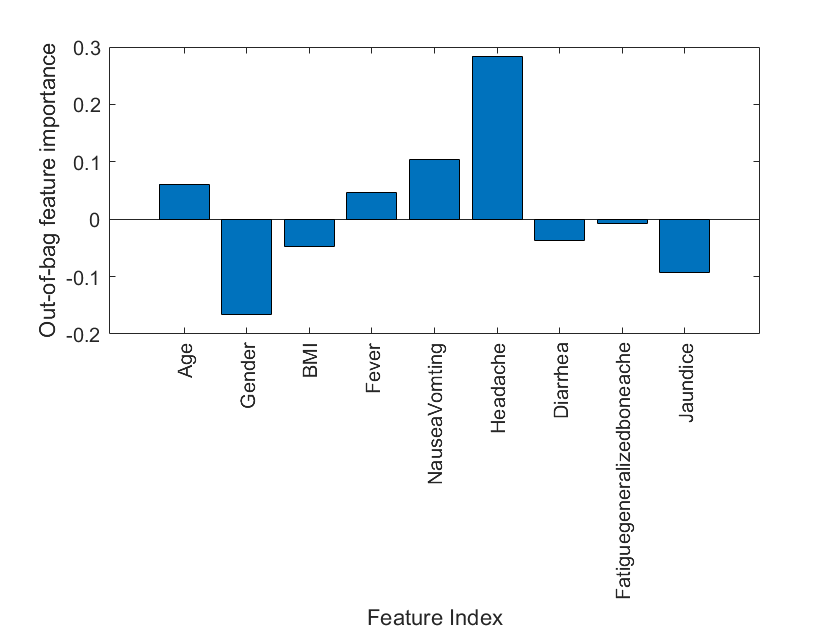

bar(RFmodel.OOBPermutedPredictorDeltaError)
xlabel('Feature Index')
ylabel('Out-of-bag feature importance')
xticklabels(HCV.Properties.VariableNames(1:28))
xtickangle(90)

Ypred=predict(RFmodel,Xtest1); % RF gives output in cell array format
Ypred=categorical(Ypred); % cell array to categorical array
sum(Ypred==Ytest1)/length(Ytest1) % accuracy

ans = 0.2332

confusionmat(double(Ytest1),double(Ypred))

Class List in given sample
     1
     2
     3
     4


Total Instance = 416
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1           8                22                45                41      
    Actual_class2          15                21                37                29      
    Actual_class3           8                18                34                34      
    Actual_class4          13                20                37                34      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      8    22    45    41
    15    21    37    29
     8    18    34    34
    13    20    37    34


## Achieved 23.32% accuracy for 5-fold using modified data.

5-Fold Cross-Validation 

x1=new_data;
y1=categorical(dat(:,29));
fold=5;
index1=crossvalind('kfold',size(Xtrain1,1),fold);
accuracy5_=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain1=x1(train,:);
    Xtest1=x1(test,:);
    Ytrain1=y1(train,:);
    Ytest1=y1(test,:);
    
    %Random Forest
    RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on");
    Ypred=predict(RFmodel,Xtest1); % RF gives output in cell array format
    Ypred=categorical(Ypred); % cell array to categorical array
   
    % For model accuracy
    accuracy5_(i)=sum(Ypred==Ytest1)/length(Ytest1);
    confusionmat(double(Ytest1),double(Ypred))
end

accuracy5_ =     0.2680         0         0         0         0


Class List in given sample
     1
     2
     3
     4


Total Instance = 194
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          14                4                 19                11      
    Actual_class2          15                4                 23                10      
    Actual_class3          17                2                 16                11      
    Actual_class4          16                4                 10                18      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =     14     4    19    11
    15     4    23    10
    17     2    16    11
    16     4    10    18


accuracy5_ =     0.2680    0.2216         0         0         0


Class List in given sample
     1
     2
     3
     4


Total Instance = 194
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          10                 6                17                14      
    Actual_class2          13                 7                13                11      
    Actual_class3          15                10                15                 9      
    Actual_class4          13                10                20                11      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =     10     6    17    14
    13     7    13    11
    15    10    15     9
    13    10    20    11


accuracy5_ =     0.2680    0.2216    0.2526         0         0


Class List in given sample
     1
     2
     3
     4


Total Instance = 194
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          11                5                  7                21      
    Actual_class2           7                6                 11                19      
    Actual_class3          24                6                 11                20      
    Actual_class4          12                4                  9                21      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =     11     5     7    21
     7     6    11    19
    24     6    11    20
    12     4     9    21


accuracy5_ =     0.2680    0.2216    0.2526    0.2642         0


Class List in given sample
     1
     2
     3
     4


Total Instance = 193
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          9                  7                22                19      
    Actual_class2          9                  6                16                13      
    Actual_class3          6                 10                19                10      
    Actual_class4          9                  9                12                17      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      9     7    22    19
     9     6    16    13
     6    10    19    10
     9     9    12    17


accuracy5_ =     0.2680    0.2216    0.2526    0.2642    0.2629


Class List in given sample
     1
     2
     3
     4


Total Instance = 194
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          12                9                 12                16      
    Actual_class2           7                7                 10                17      
    Actual_class3          14                4                 16                11      
    Actual_class4          18                6                 19                16      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =     12     9    12    16
     7     7    10    17
    14     4    16    11
    18     6    19    16


accuracy5_

accuracy5_ =     0.2680    0.2216    0.2526    0.2642    0.2629


avg_accuracy_5=mean(accuracy5_)

avg_accuracy_5 = 0.2539

## Achieved 25.39% accuracy for 5-fold using modified data.

10-Fold Cross-Validation 

x1=new_data;
y1=categorical(dat(:,29));
fold=10;
index1=crossvalind('kfold',size(Xtrain1,1),fold);
accuracy10_=zeros(1,fold);
%Model 1
for i=1:fold
    test=(index1==i);
    train=~test;
    Xtrain1=x1(train,:);
    Xtest1=x1(test,:);
    Ytrain1=y1(train,:);
    Ytest1=y1(test,:);
    
    %Random Forest
    RFmodel=TreeBagger(100,Xtrain1,Ytrain1,'MinLeafSize',10,'OOBPrediction',"on",'OOBPredictorImportance',"on");
    Ypred=predict(RFmodel,Xtest1); % RF gives output in cell array format
    Ypred=categorical(Ypred); % cell array to categorical array
   
    % For model accuracy
    accuracy10_(i)=sum(Ypred==Ytest1)/length(Ytest1);
    confusionmat(double(Ytest1),double(Ypred))
end

Class List in given sample
     1
     2
     3
     4


Total Instance = 78
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          3                 3                 4                 4       
    Actual_class2          7                 4                 6                 6       
    Actual_class3          4                 3                 7                 6       
    Actual_class4          5                 3                 6                 7       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      3     3     4     4
     7     4     6     6
     4     3     7     6
     5     3     6     7


Class List in given sample
     1
     2
     3
     4


Total Instance = 77
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          6                 4                 9                 5       
    Actual_class2          4                 2                 9                 4       
    Actual_class3          3                 4                 6                 7       
    Actual_class4          0                 2                 4                 8       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      6     4     9     5
     4     2     9     4
     3     4     6     7
     0     2     4     8


Class List in given sample
     1
     2
     3
     4


Total Instance = 77
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          2                 2                 4                 8       
    Actual_class2          7                 3                 2                 7       
    Actual_class3          8                 2                 6                 8       
    Actual_class4          4                 4                 6                 4       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      2     2     4     8
     7     3     2     7
     8     2     6     8
     4     4     6     4


Class List in given sample
     1
     2
     3
     4


Total Instance = 78
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          2                 5                  9                4       
    Actual_class2          3                 1                  5                2       
    Actual_class3          8                 1                 13                5       
    Actual_class4          5                 3                  6                6       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      2     5     9     4
     3     1     5     2
     8     1    13     5
     5     3     6     6


Class List in given sample
     1
     2
     3
     4


Total Instance = 78
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          0                 6                  7                1       
    Actual_class2          3                 3                  6                1       
    Actual_class3          3                 5                 11                6       
    Actual_class4          5                 1                 13                7       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      0     6     7     1
     3     3     6     1
     3     5    11     6
     5     1    13     7


Class List in given sample
     1
     2
     3
     4


Total Instance = 77
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          6                 3                 10                3       
    Actual_class2          4                 2                  8                5       
    Actual_class3          2                 3                  6                4       
    Actual_class4          5                 0                  7                9       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      6     3    10     3
     4     2     8     5
     2     3     6     4
     5     0     7     9


Class List in given sample
     1
     2
     3
     4


Total Instance = 78
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          0                 3                  8                7       
    Actual_class2          3                 5                  6                8       
    Actual_class3          1                 1                 13                5       
    Actual_class4          4                 0                  6                8       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      0     3     8     7
     3     5     6     8
     1     1    13     5
     4     0     6     8


Class List in given sample
     1
     2
     3
     4


Total Instance = 77
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          3                 2                  9                7       
    Actual_class2          4                 3                 11                2       
    Actual_class3          4                 2                  7                5       
    Actual_class4          4                 3                  4                7       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      3     2     9     7
     4     3    11     2
     4     2     7     5
     4     3     4     7


Class List in given sample
     1
     2
     3
     4


Total Instance = 77
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          2                 3                 10                7       
    Actual_class2          3                 2                  1                7       
    Actual_class3          2                 4                  5                8       
    Actual_class4          8                 3                  8                4       

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      2     3    10     7
     3     2     1     7
     2     4     5     8
     8     3     8     4


Class List in given sample
     1
     2
     3
     4


Total Instance = 78
class1==>1
class2==>2
class3==>3
class4==>4
Confusion Matrix
                     predict_class1    predict_class2    predict_class3    predict_class4
                     ______________    ______________    ______________    ______________

    Actual_class1          4                 1                 6                 12      
    Actual_class2          4                 2                 8                  6      
    Actual_class3          4                 2                 7                  2      
    Actual_class4          4                 3                 9                  4      

Multi-Class Confusion Matrix Output
                     TruePositive    FalsePositive

ans =      4     1     6    12
     4     2     8     6
     4     2     7     2
     4     3     9     4


accuracy10_

accuracy10_ =     0.2692    0.2857    0.1948    0.2821    0.2692    0.2987    0.3333    0.2597    0.1688    0.2179


avg_accuracy_10=mean(accuracy10_)

avg_accuracy_10 = 0.2580

## Achieved 25.80% accuracy for 10-fold using modified data.